%addpath('/home/glen/OneDrive/Work/FACET2/GPT')% for save_struct_to_gdf_file.m and other functions
%% Track with GPT to the end of L0a
FI = GPT_FacetInjector_NMM();

emitHist = [];



%for laserPulseSpacingSet = 8.6e-12:2e-12:8.6e-12 %dt = 8.6 gives approx 2.2 mm spacing
%for linacPhaseSet = 284:5:284 %2 nC, single bunch was happy at 290. Double bunch is happier around 284.

linacPhaseSet = 284.0;
laserPulseSpacingSet = 8.6e-12;
FI.L0a_phase = linacPhaseSet;
FI.dt = laserPulseSpacingSet;
FI.StoreVec = false;

%Two bunch settings
FI.sigt = [2.2e-12 2.2e-12];
FI.Q0 = [0.5e-9 1.6e-9];

%FI.Q0 = 2.0e-9;
fprintf('Linac phase setting: %.2f\n', linacPhaseSet);

Linac phase setting: 284.00


fprintf('Laser pulse spacing: %e\n', laserPulseSpacingSet);

Laser pulse spacing: 8.600000e-12



%Write GPT beam and run files then run GPT
FI.MakeCathodeBeam;
FI.writeBeamFile(FI.Beam);
%FI.writeBeamFile(FI.BeamSingle,'single');
iseed = 1;
FI.writeRunFile(iseed);

Time offset phase correction [degrees]: -5.14
GPT phase [degrees]: 294.86


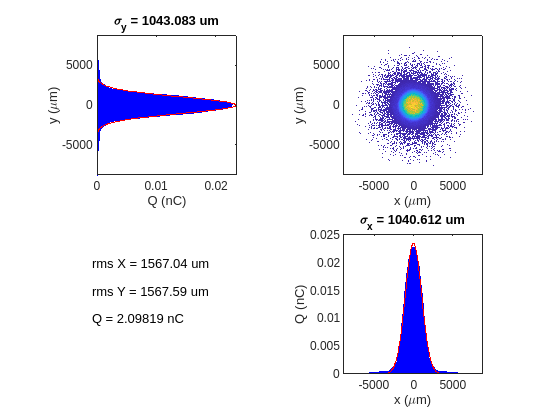

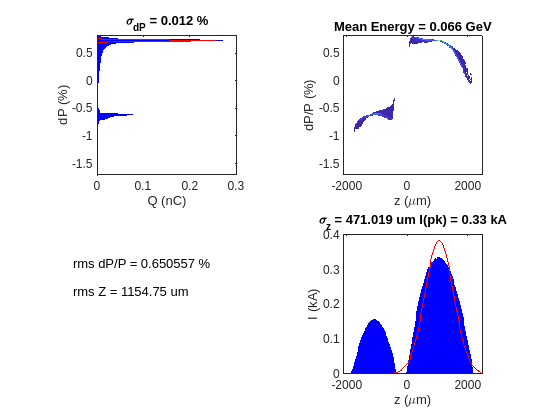

ans = struct with fields:
    sigy: 1.0431e+03
    sigx: 1.0406e+03
    rmsx: 1.5670e+03
    rmsy: 1.5676e+03
    sigE: 0.0120
    sigz: 471.0191
     pkI: 0.3349
    rmsz: 1.1548e+03
    rmsE: 0.6506


sid=system(sprintf('gpt -o %s %s > /dev/null 2>&1',sprintf('result_%d.gdf',iseed),sprintf('GPT_%d.in',iseed)));


%% Read the simulation data
[Bout,xv,yv,zv,ev,emitXvec]=FI.readData(1);
beamImage(Bout{1})

[nx,ny,nz]=GetNEmitFromBeam(Bout{1},1)

nx = 8.0876e-06

ny = 8.0969e-06

nz = 0.0039

[nx90,ny90,nz90,~,~]=GetNEmit90FromBeam(Bout{1})

nx90 = 5.5004e-06

ny90 = 5.5073e-06

nz90 = 4.5971e-04

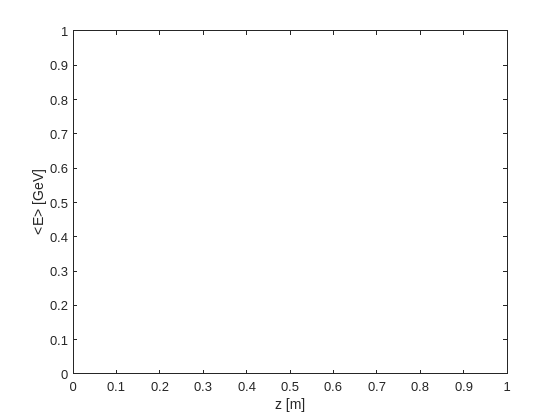



figure; %NMM: This command prevents this new plot from being added as a subplot
plot(mean(zv,2,'omitnan'),mean(ev,2,'omitnan')) %NMM: Plot average energy vs average z
xlabel('z [m]');
ylabel('<E> [GeV]');

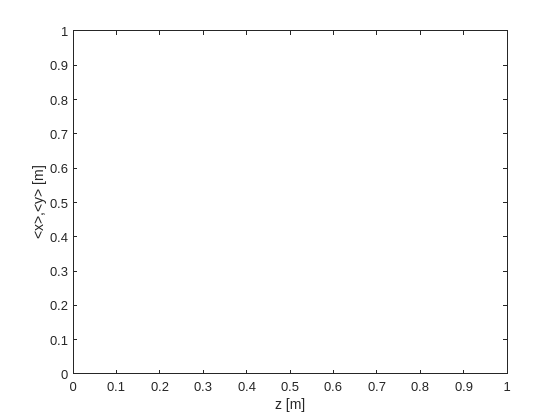


figure;
plot(mean(zv,2,'omitnan'),mean(xv,2,'omitnan'),mean(zv,2,'omitnan'),mean(yv,2,'omitnan'))
xlabel('z [m]');
ylabel('<x>,<y> [m]');

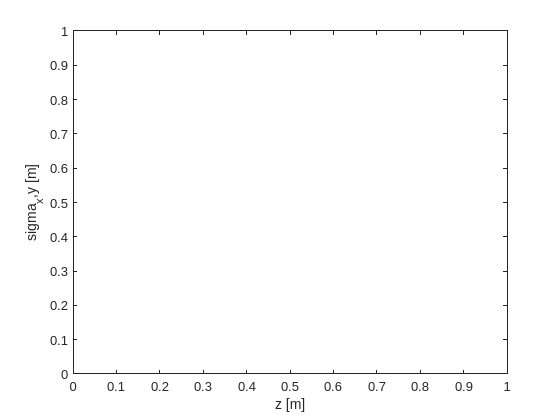


figure;
plot(mean(zv,2,'omitnan'),std(xv,0,2,'omitnan'),mean(zv,2,'omitnan'),std(yv,0,2,'omitnan'))
xlabel('z [m]');
ylabel('sigma_x,y [m]');

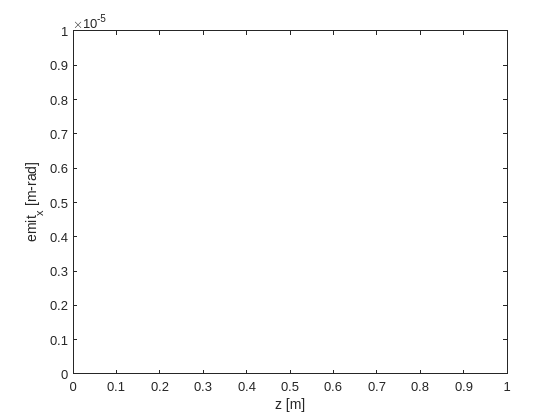


figure;
plot(mean(zv,2,'omitnan'),emitXvec)
xlabel('z [m]');
ylabel('emit_x [m-rad]');
ylim([0,10e-6]);

%figure;
%plot(mean(zv,2,'omitnan'),mean(yv,2,'omitnan'))



%emitHist{end+1} = [linacPhaseSet,nx,ny,nz]; %NMM: This makes a cell array
emitHist =  [ emitHist; linacPhaseSet,nx,ny,nz]; %NMM: This makes a normal, numeric array

%slice_twiss_params_Lucretia(Bout{1},100)


%end
%end

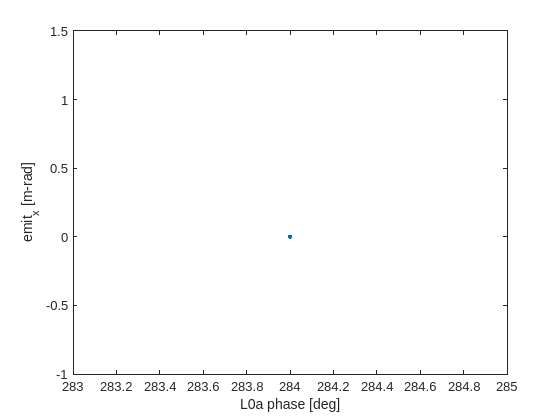

figure;
plot(emitHist(:,1),emitHist(:,2),'.')
xlabel('L0a phase [deg]')
ylabel('emit_x [m-rad]')

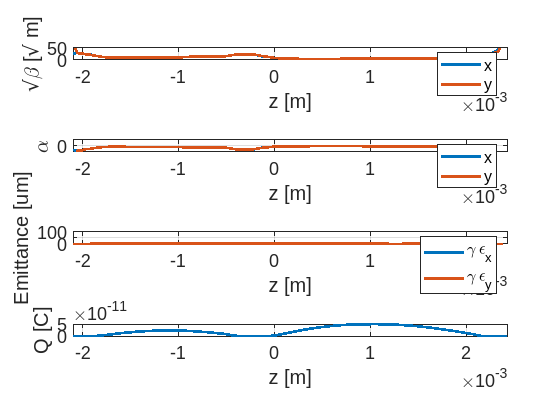

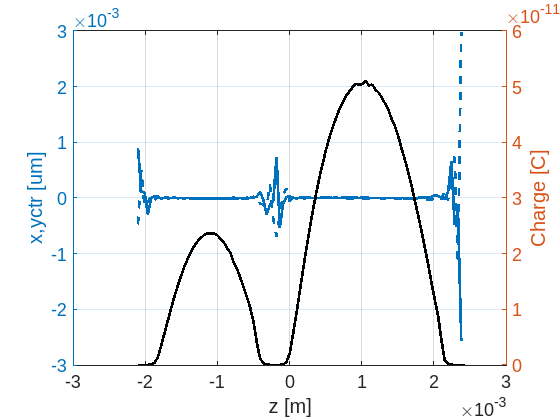

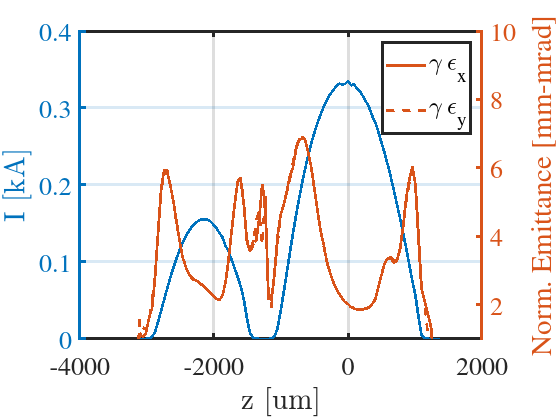

Index exceeds the number of array elements. Index must not exceed 100.

Error in Execute_live>slice_twiss_params_Lucretia (line 188)
        qslice = trapz(zplot(idy),charge(idy));

save('beamAtL0AFEND_2bunch','Bout')
slice_twiss_params_Lucretia(Bout{1},100)

function [betax,betay,alphax,alphay,emitx,emity,slicez,I,xrms,yrms] = slice_twiss_params_Lucretia(beam,nslice)
    % Filter out stopped particles
    idx = ~beam.Bunch.stop;
    
    % Extract position and momentum coordinates
    x = beam.Bunch.x(1,idx); xp = beam.Bunch.x(2,idx);
    y = beam.Bunch.x(3,idx); yp = beam.Bunch.x(4,idx);
    z = 1.0*beam.Bunch.x(5,idx); gamma = beam.Bunch.x(6,idx)/0.511e-3;
    q = beam.Bunch.Q(idx);
    
    % Create slice bins along z
    slicez = linspace(min(z),max(z),nslice+1);
    dz = abs(slicez(2)-slicez(1));
    
    % Loop over slices to calculate Twiss parameters
    for n=1:length(slicez)-1
        idz = z < slicez(n+1) & z > slicez(n);
        gamma_slice = mean(gamma(idz));
        x_slice = x(idz);  xp_slice = xp(idz);
        y_slice = y(idz);  yp_slice = yp(idz);
        
        % Calculate emittance for x and y
        emitx(n)=gamma_slice.*sqrt(mean(x_slice.^2)*mean(xp_slice.^2)-mean(x_slice.*xp_slice).^2);
        emity(n)=gamma_slice.*sqrt(mean(y_slice.^2)*mean(yp_slice.^2)-mean(y_slice.*yp_slice).^2);
        
        % Calculate beta for x and y
        betax(n)=mean(x_slice.*x_slice).*gamma_slice./emitx(n);
        betay(n)=mean(y_slice.*y_slice).*gamma_slice./emity(n);
        
        % Calculate alpha for x and y
        alphax(n)=-mean(x_slice.*xp_slice).*gamma_slice./emitx(n);
        alphay(n)=-mean(y_slice.*yp_slice).*gamma_slice./emity(n);
        
        % Calculate charge, RMS size and mean position for the slice
        charge(n) = sum(q(idz));
        xrms(n) = std(x_slice);
        yrms(n) = std(y_slice);
        xctr(n) = mean(x_slice);
        yctr(n) = mean(y_slice);
    end
    
    % Calculate current profile (3e8 is speed of light in cm/s)
    I = 3e8*charge/dz;
    
    % Find the index corresponding to the maximum current
    [~,idx]= max(I);
    zplot = 1e6*dz*([1:length(I)]-idx);
    
    % Plot Twiss parameters in subplots
    figure
    subplot(4,1,1) % Subplot for sqrt(beta)
    plot(slicez(1:end-1),sqrt(betax),'LineWidth',2);hold on
    plot(slicez(1:end-1),sqrt(betay),'LineWidth',2)
    xlabel('z [m]');ylabel('\surd\beta [\surd m]');legend('x','y');grid on;set(gca,'FontSize',14)
    ylim([0,50]);xlim([slicez(1),slicez(end-1)])
    
    subplot(4,1,2) % Subplot for alpha
    plot(slicez(1:end-1),alphax,'LineWidth',2);hold on
    plot(slicez(1:end-1),alphay,'LineWidth',2)
    xlabel('z [m]');ylabel('\alpha');legend('x','y');grid on;set(gca,'FontSize',14)
    ylim([-100,100]);xlim([slicez(1),slicez(end-1)])
    
    subplot(4,1,3) % Subplot for emittance
    plot(slicez(1:end-1),emitx*1e6,'LineWidth',2);hold on
    plot(slicez(1:end-1),emity*1e6,'LineWidth',2)
    xlabel('z [m]');ylabel('Emittance [um]');legend('\gamma \epsilon_x','\gamma \epsilon_y');grid on;set(gca,'FontSize',14)
    ylim([0,100]);xlim([slicez(1),slicez(end-1)])
    
    subplot(4,1,4) % Subplot for charge
    plot(slicez(1:end-1),charge,'LineWidth',2);
    xlabel('z [m]');ylabel('Q [C]');grid on;set(gca,'FontSize',14);xlim([slicez(1),slicez(end-1)])
    
    % Another figure for mean position and charge
    figure
    yyaxis left % Left y-axis for mean position
    plot(slicez(1:end-1),xctr,'LineWidth',2);hold on;plot(slicez(1:end-1),yctr,'LineWidth',2);
    ylabel('x,yctr [um]')
    yyaxis right % Right y-axis for charge
    plot(slicez(1:end-1),charge,'k','LineWidth',2);
    xlabel('z [m]');ylabel('Charge [C]');grid on;set(gca,'FontSize',14)
    
    % Another figure for current and normalized emittance
    figure
    yyaxis left
    h1=plot(zplot,I*1e-3,'LineWidth',2); % Store plot handle for legend
    xlabel('z [$\mu$m]','interpreter','latex') ;
    ylabel('I [kA]','interpreter','latex') ;grid on;
    yyaxis right
    h2 = plot(zplot,emitx*1e6,'LineWidth',2);hold on % Store plot handle for legend
    h3 = plot(zplot,emity*1e6,'LineWidth',2); % Store plot handle for legend
    ylim([1,10])
    xlabel('z [um]');ylabel('Norm. Emittance [mm-mrad]');legend([h2,h3],{'\gamma \epsilon_x','\gamma \epsilon_y'});grid on;
    set(gca,'FontSize',20,'FontName','Times','LineWidth',2)
    
    % Calculate total charge using trapezoidal integration (trapz)
    qtot = trapz(zplot,charge);
    
    % Find the index for the center-of-mass slice
    idx = round(sum(idx.*charge)/sum(charge));
    n=1;
    idy = idx-n:idx+n;
    
    % Calculate total charge in slices containing 90% of total charge using trapezoidal integration (trapz)
    qslice = trapz(zplot(idy),charge(idy));
    while qslice<0.9*qtot
        idy = idx-n:idx+n;
        qslice = trapz(zplot(idy),charge(idy));
        n = n+1;
    end
    
    % Compute mean Twiss parameters for the 90% charge region
    emitnx90 = mean(emitx(idy))
    emitny90 = mean(emity(idy))
    betax90 = mean(betax(idy))
    betay90 = mean(betay(idy))
    alphax90 = mean(alphax(idy))
    alphay90 = mean(alphay(idy))
end



